clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

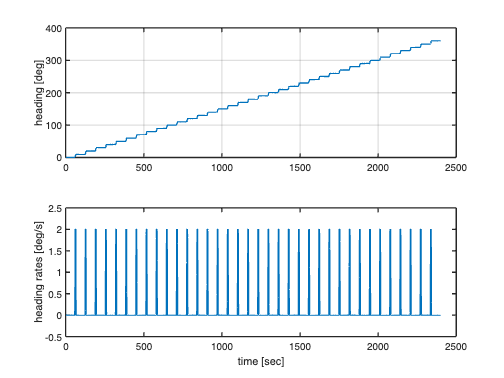

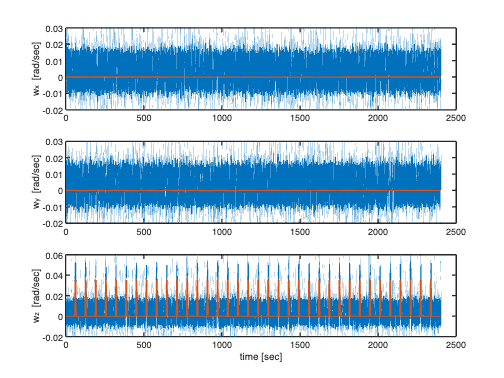

%% collected data from simulation

BW                  = 200;            % IMU sample rate in [Hz]
simulation          = sim_fixed_pos(BW);


% Noisy data
wx_noisy            = simulation.gyro_x_noisy;
wy_noisy            = simulation.gyro_y_noisy;
wz_noisy            = simulation.gyro_z_noisy;

% Error Free data
wx_free             = simulation.gyro_x_ref;
wy_free             = simulation.gyro_y_ref;
wz_free             = simulation.gyro_z_ref;

% simulation profile heading and heading rates
psi                 = simulation.psi;
psi_dot             = simulation.psi_dot;

% %% Deterministic and Stochastic errors
bias_gyro           = simulation.bias_gyro;
SF_gyro             = simulation.SF_gyro;
ARW                 = simulation.ARW;

% % Split the data into training and testing sets
split_ratio             = 0.8; % 60% training, 20% validation, 20% testing
num_samples             = size(wz_noisy, 1);
split_idx_train         = round(split_ratio * num_samples);
split_idx_val           = round(0.8 * num_samples); 


%% split the data to training, validation and testing, including the reference data
%% Training sets
train_data          = num2cell(wz_noisy(1:split_idx_val, :),1);
train_labels        = num2cell(psi(1:split_idx_val, :),1);

%% Testing sets
test_data           = (wz_noisy(split_idx_val+1:end, :))';
test_labels         = (psi(split_idx_val+1:end, :))';

%% since I need my input size to the NN to be 1, I need to change the
%% appearance of the cell array, where each cell of both data & labels
%% to be 1xsplit_idx & 1xsplit_id+1:end respectively

train_data{:}       = train_data{:}';
train_labels{:}     = train_labels{:}';


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |     7.71e-03 |        139.0 |          0.0003 |
|       1 |          50 |       00:00:09 |         3.88 |          4.9 |          0.0003 |
|       2 |         100 |       00:00:09 |         2.68 |          7.2 |          0.0003 |
|       3 |         150 |       00:00:10 |         1.49 |          7.4 |          0.0003 |
|       4 |         200 |       00:00:12 |         0.31 |          5.6 |          0.0003 |
|       4 |         250 |       00:00:13 |         4.34 |          1.6 |          0.0003 |
|       5 |         300 |       00:00:14 |         3.14 |      1.7

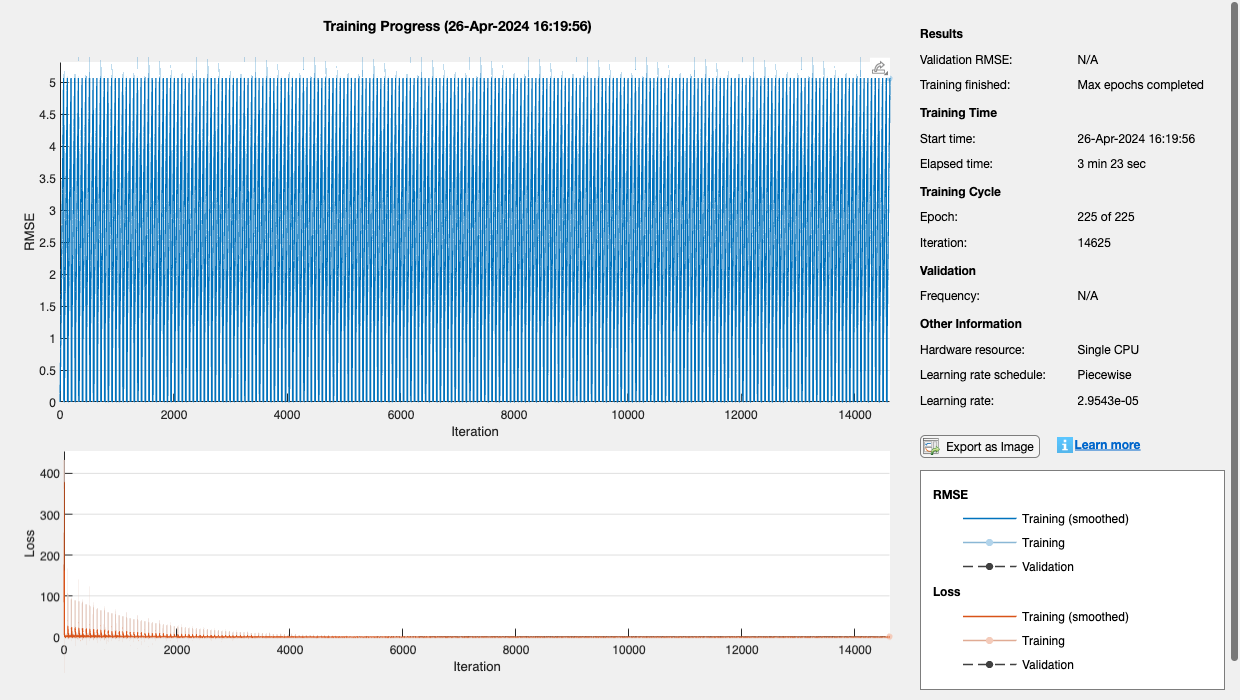

% configure neural network (NN)
numFeatures     = size(train_data, 1); % Number of features in your data
numResponses    = 1;

layers = [
    sequenceInputLayer(numFeatures)
    fullyConnectedLayer(numResponses, 'Name', 'output')
    StrapdownRegressionLayer('1D-StrapdownRegression')
];


% Set training options with the Adam optimizer
options = trainingOptions('adam', ...
    'MaxEpochs', 225, ...
    'MiniBatchSize', 2^5, ...
    'SequenceLength', 6000, ... % Adjust as needed
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.0003, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.9, ...
    'LearnRateDropPeriod', 10, ...
    'Shuffle', 'every-epoch', ...  % to reduce biases in training
    'ExecutionEnvironment', 'auto', ...
    'Plots','training-progress',...
    'Verbose',1);

% Train the LSTM network
net = trainNetwork(train_data, train_labels, layers, options);


% Test the trained network
predicted_labels = predict(net, test_data);
predicted_labels = cumsum(predicted_labels)/BW;

predicted_psi0  = predicted_labels + (test_labels(1,1)-predicted_labels(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and course alignment done
uncalibrated_data = cumsum(test_data)/BW;
uncalibrated_data = uncalibrated_data + (test_labels(1,1)-uncalibrated_data(1,1)); % course alignment

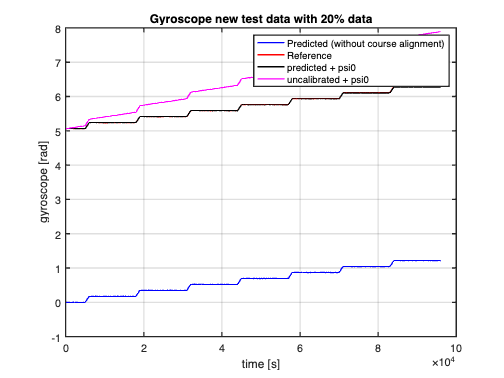

%% Plots
fig1=figure;
plot(predicted_labels,'b')
hold on;
plot(test_labels, 'r')
plot(predicted_psi0,'k')
plot(uncalibrated_data,'m')
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new test data with 20% data');
exportgraphics(fig1,'Gyroscope new test data with 20% data.png','Resolution',300);

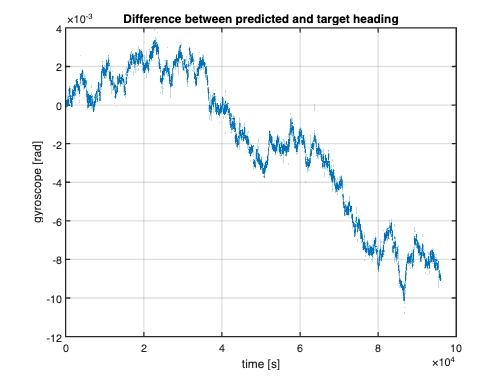


fig2=figure;
plot(predicted_psi0-test_labels);
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
title('Difference between predicted and target heading');
exportgraphics(fig2,'Difference between predicted and target heading.png','Resolution',300);

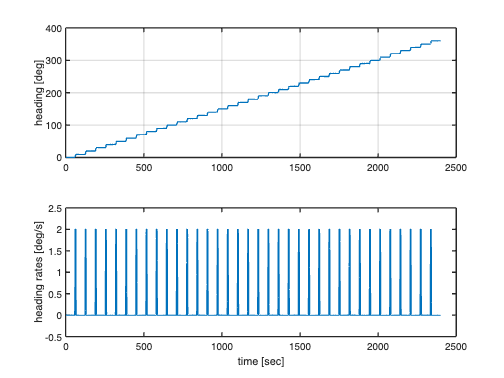

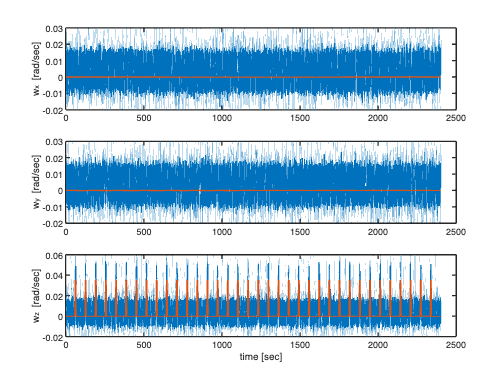

% New data - simulation runs another random data
simulation          = sim_fixed_pos(BW);

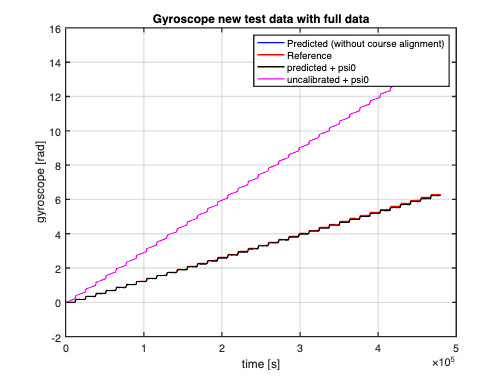


% Noisy data
new_input_1            = (simulation.gyro_z_noisy)';

% simulation profile heading and heading rates
new_ref_1              = simulation.psi;

new_predict_1 = predict(net, new_input_1);
new_predict_1 = new_predict_1';
new_predict_1 = cumsum(new_predict_1)/BW;
new_predicted_1_psi0  = new_predict_1 + (new_ref_1(1,1)-new_predict_1(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and course alignment done
new_uncalibrated_data_1 = (cumsum(new_input_1)/BW)';
new_uncalibrated_data_1 = new_uncalibrated_data_1 + (new_ref_1(1,1)-new_uncalibrated_data_1(1,1)); % course alignment

%% Plots
fig3=figure;
plot(new_predict_1,'b')
hold on;
plot(new_ref_1, 'r')
plot(new_predicted_1_psi0,'k')
plot(new_uncalibrated_data_1,'m')
grid on
hold off
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new test data with full data');
exportgraphics(fig3,'Gyroscope new test data with full data.png','Resolution',300);

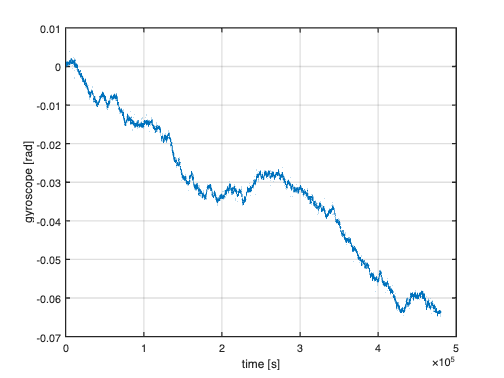


fig4=figure;
plot(new_predicted_1_psi0-new_ref_1);
xlabel('time [s]');
ylabel('gyroscope [rad]');
grid on
exportgraphics(fig4,'Difference Plot new test data.png','Resolution',300);

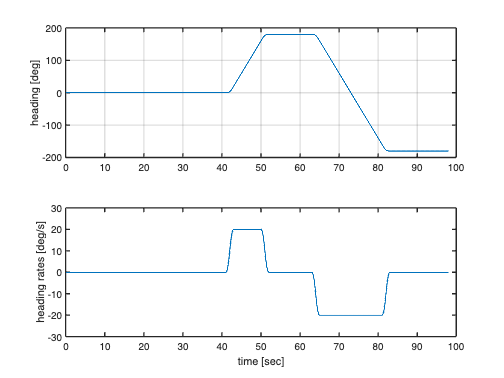

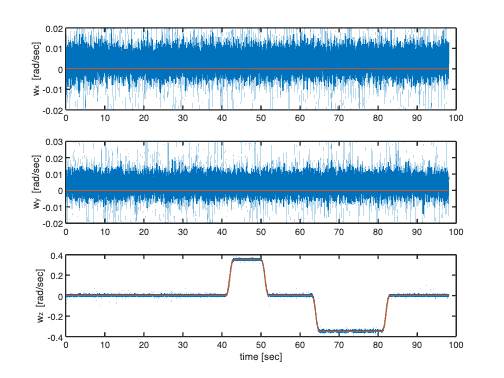

% New trajectory simulated
simulation2          = sim_fixed_pos2(BW);

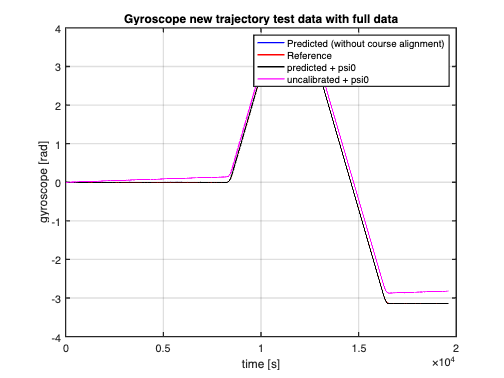


% Noisy data
new_input_2            = (simulation2.gyro_z_noisy)';

% simulation profile heading and heading rates
new_ref_2              = simulation2.psi;

new_predict_2 = predict(net, new_input_2);
new_predict_2 = new_predict_2';
new_predict_2 = cumsum(new_predict_2)/BW;
new_predicted_psi0_2  = new_predict_2 + (new_ref_2(1,1)-new_predict_2(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and course alignment done
new_uncalibrated_data_2 = cumsum(new_input_2)/BW;
new_uncalibrated_data_2 = new_uncalibrated_data_2 + (new_ref_2(1,1)-new_uncalibrated_data_2(1,1)); % course alignment

%% Plots
fig5=figure;
plot(new_predict_2,'b')
hold on;
plot(new_ref_2, 'r')
plot(new_predicted_psi0_2,'k')
plot(new_uncalibrated_data_2,'m')
grid on
hold off
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new trajectory test data with full data');
exportgraphics(fig5,'Gyroscope new trajectory test data with full data.png','Resolution',300);

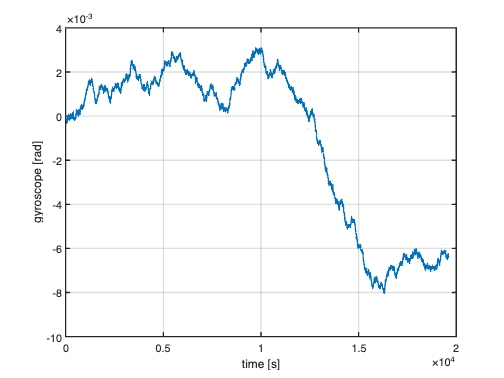


fig6=figure;
plot(new_predicted_psi0_2-new_ref_2);
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
exportgraphics(fig6,'Difference Plot new test data.png','Resolution',300);

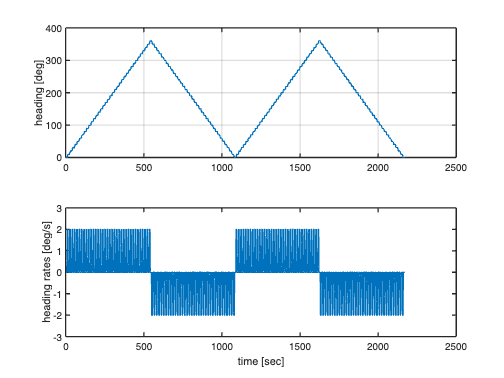

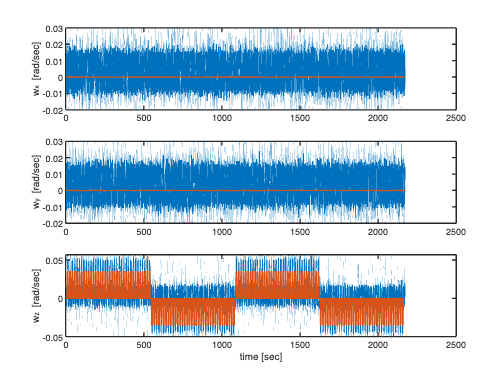

% New trajectory simulated (longer dataset)
simulation3          = sim_fixed_pos3(BW);

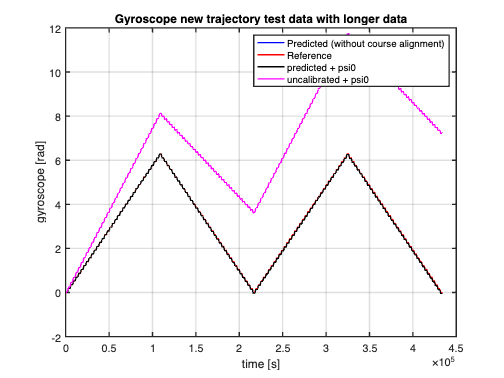

% Noisy data
new_input_3            = (simulation3.gyro_z_noisy)';

% simulation profile heading and heading rates
new_ref_3              = simulation3.psi;

new_predict_3 = predict(net, new_input_3);
new_predict_3 = new_predict_3';
new_predict_3 = cumsum(new_predict_3)/BW;
new_predicted_psi0_3  = new_predict_3 + (new_ref_3(1,1)-new_predict_3(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and course alignment done
new_uncalibrated_data_3 = (cumsum(new_input_3)/BW)';
new_uncalibrated_data_3 = new_uncalibrated_data_3 + (new_ref_3(1,1)-new_uncalibrated_data_3(1,1)); % course alignment

%% Plots
fig7=figure;
plot(new_predict_3,'b')
hold on;
plot(new_ref_3, 'r')
plot(new_predicted_psi0_3,'k')
plot(new_uncalibrated_data_3,'m')
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new trajectory test data with longer data');
exportgraphics(fig7,'Gyroscope new trajectory test data with longer data.png','Resolution',300);

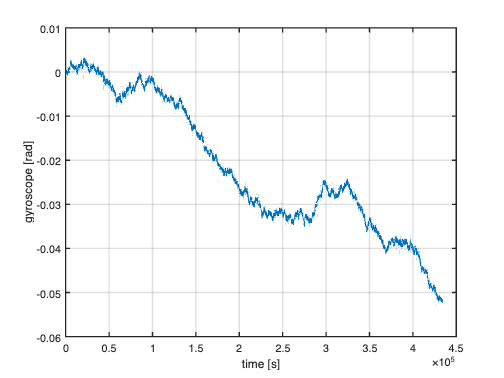


fig8=figure;
plot(new_predicted_psi0_3-new_ref_3);
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
exportgraphics(fig8,'Difference with new trajectory longer data.png','Resolution',300);

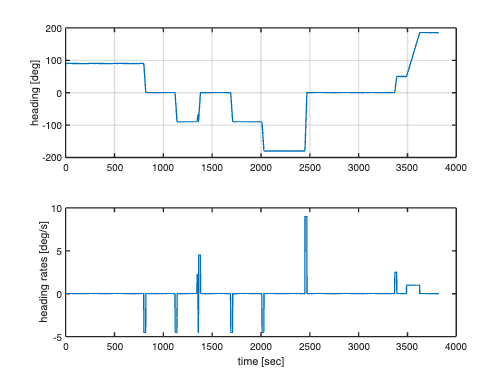

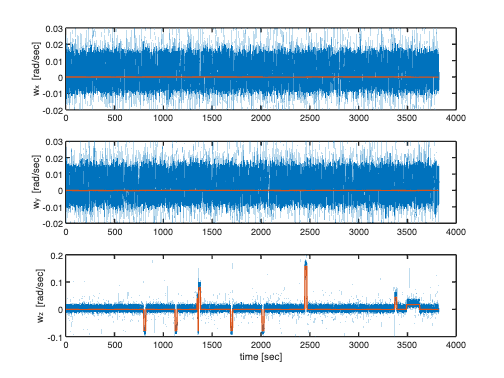

% New trajectory simulated (longer dynamic dataset)
BW2                   = 100;
simulation4          = sim_fixed_pos4(BW2);

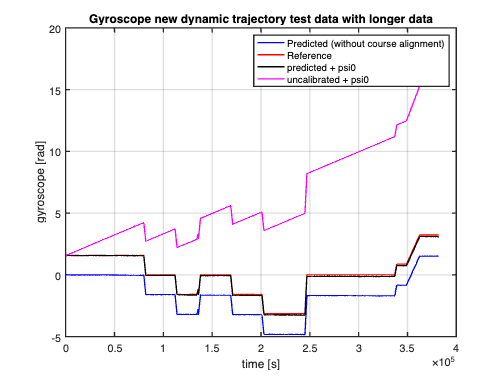

% Noisy data
new_input_4            = (simulation4.gyro_z_noisy)';

% simulation profile heading and heading rates
new_ref_4              = simulation4.psi;

new_predict_4 = predict(net, new_input_4);
new_predict_4 = new_predict_4';
new_predict_4 = cumsum(new_predict_4)/100;
new_predicted_psi0_4  = new_predict_4 + (new_ref_4(1,1)-new_predict_4(1,1)); % course alignment

% Test data that hasn't gone through network but still intergrated and course alignment done
new_uncalibrated_data_4 = (cumsum(new_input_4)/BW2)';
new_uncalibrated_data_4 = new_uncalibrated_data_4 + (new_ref_4(1,1)-new_uncalibrated_data_4(1,1)); % course alignment

%% Plots
fig9=figure;
plot(new_predict_4,'b')
hold on;
plot(new_ref_4, 'r')
plot(new_predicted_psi0_4,'k')
plot(new_uncalibrated_data_4,'m')
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
legend('Predicted (without course alignment)','Reference','predicted + psi0','uncalibrated + psi0');
title('Gyroscope new dynamic trajectory test data with longer data');
exportgraphics(fig9,'Gyroscope new dynamic trajectory test data with full data.png','Resolution',300);

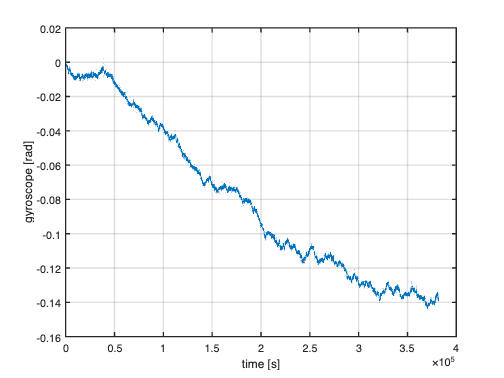



fig10=figure;
plot(new_predicted_psi0_4-new_ref_4);
grid on
xlabel('time [s]');
ylabel('gyroscope [rad]');
exportgraphics(fig10,'Difference new dynamic trajectory test data .png','Resolution',300);